## Lagrange Interpolation

In this livescript, you will learn how

- To use Lagrange interpolation approximate functions

Consider two points $(x_{0},y_{0})$ and $(x_{1},y_{1})$

(a)        Show that linearly interpolating between these two points yields the linear relationship


$$y=ax+b$$


where 


$$a=\frac{y_{1}-y_{0}}{x_{1}-x_{0}}$$



$$b=\frac{y_{0}(x_{1}-x_{0})-(y_{1}-y_{0})x_{0}}{x_{1}-x_{0}}$$


(b)        Show that this may be rearranged into the form


$$y=y_{0}\Big(\frac{x-x_{1}}{x_{0}-x_{1}}\Big)+y_{1}\Big(\frac{x-x_{0}}{x_{1}-x_{0}}\Big)$$


(c)        Consider the set of three points $\{(x_{0},y_{0}),(x_{1},y_{1}),(x_{2},y_{2})\}$. Repeat parts (a) and (b) and show that the quadratic interpolating polynomial is given by


$$y=y_{0}\Bigg(\frac{(x-x_{1})(x-x_{2})}{(x_{0}-x_{1})(x_{0}-x_{2})}\Bigg)
+
y_{1}\Bigg(\frac{(x-x_{0})(x-x_{2})}{(x_{1}-x_{0})(x_{1}-x_{2})}\Bigg)
+
y_{2}
\Bigg(\frac{(x-x_{0})(x-x_{1})}{(x_{2}-x_{0})(x_{2}-x_{1})}\Bigg)$$


It turns out that in general, we may write the interpolating polynomial in the form


$$p(x)=\sum^{N}_{i=0}{y_{i}L_{i}(x)$$


*Equation 1.*

where 


$$L_{i}(x)=\prod^{N}_{j=0,j\neq i}{\frac{x-x_{j}}{x_{i}-x_{j}}}=\frac{x-x_{0}}{x_{j}-x_{0}}\cdots\frac{x-x_{i-1}}{x_{i}-x_{i-1}}\frac{x-x_{i+1}}{x_{i}-x_{i+1}}\cdots\frac{x-x_{N}}{x_{i}-x_{N}}$$


Essentially, what this says is that the Lagrange basis $\{L_{i}\}$ is 1 at the $i^{\text{th}}$ nodal point and 0 everywhere else. This is what is known as the **Lagrange interpolation property**.

To implement this in MATLAB, the following piece of code determines the lagrange basis polynomials

x = 1;
xs = [0,1,4];

i = 1;
L = 1;

for j = 1:length(xs)
    if j~=i
        L = L*(x-xs(j))/(xs(i)-xs(j));
    end
end

L

L = 0

(d)        Run this piece of code and understand each line of code does.

(e)        Generalise the code so that it can take a vector $\texttt{x}$ as an input.

To determine how this works, we'll consider the test function


$$f(x)=e^{x}$$


And interpolate it with 2 points between $0\leq x \leq 1$.

The function values at the nodes is given by

nodes = linspace(0,1,2);
f = exp(nodes);

For convinence, the previous piece of code is placed in a MATLAB function $\texttt{lagrange\_L(i,x\_nodes,x\_points)}$. Hence the interpolating polynomial is given by

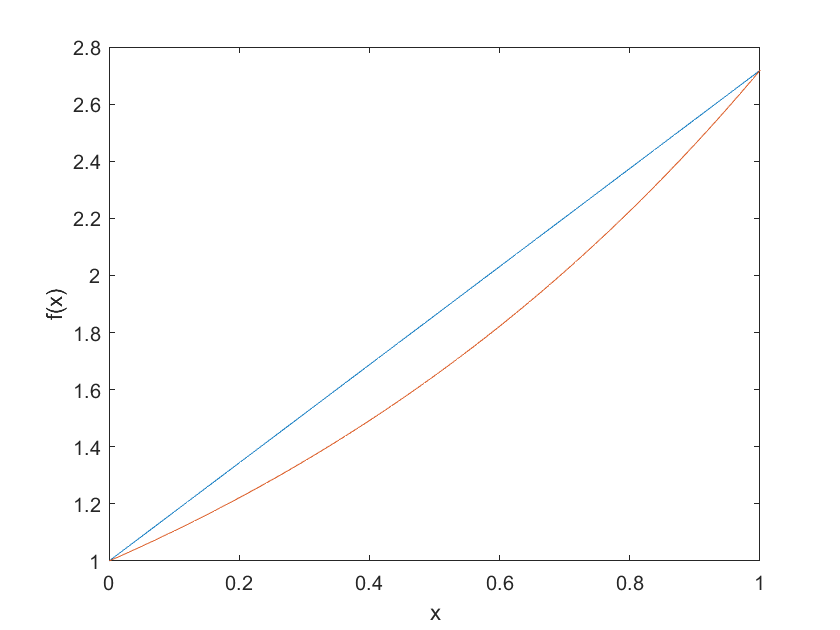

x1 = linspace(0,1,100);
y1 = 0;

for l = 1:length(nodes)
    y1 = y1+f(l)*lagrange_L(l,nodes,x1);
end

plot(x1,y1)
hold on
plot(x1,exp(x1))
xlabel('x')
ylabel('f(x)')
hold off

The error is therefore

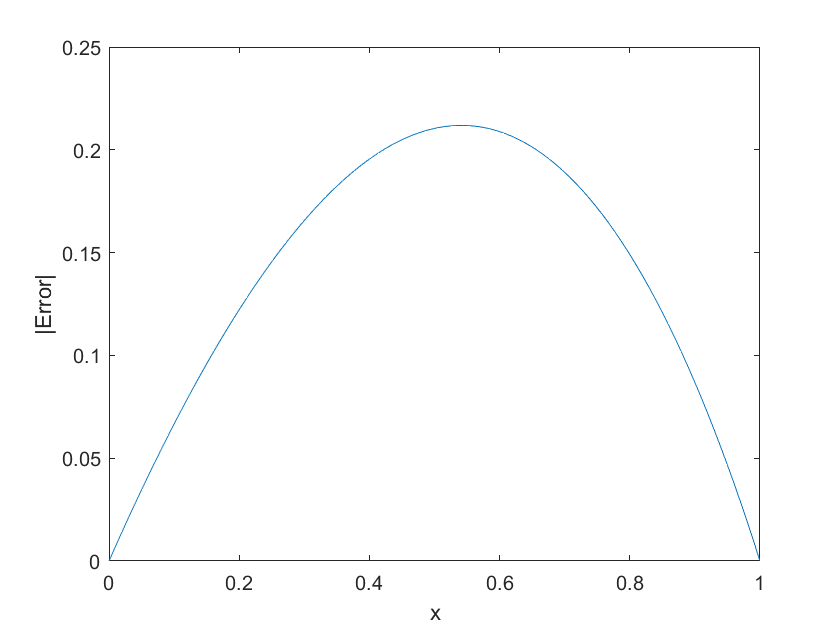

Error = abs(y1'-exp(x1));
plot(x1,Error)
xlabel('x')
ylabel('|Error|')

(e)        Modify the code to use 3 and 4 interpolating nodes between $0\leq x \leq 1$. Does the accuracy of the approximation increase?